syms tc f_t
f_tc=sin(tc)

$$f\_tc = \sin\left(\mathrm{tc}\right)$$


fplot(f_tc,[0,2*pi],"-")

t = linspace(0,2*pi,101)

t =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


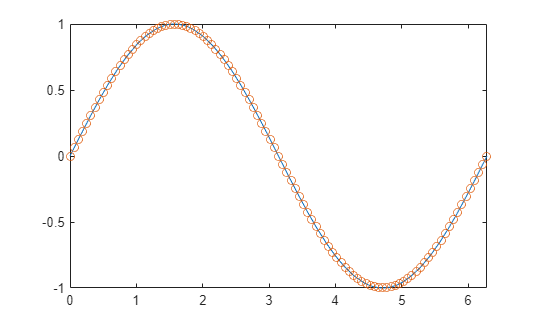

f_t=sin(t);
hold on
plot (t,f_t,"o")
hold off

## Derivatives

dfdt_c=diff(f_tc,tc)

$$dfdt\_c = \cos\left(\mathrm{tc}\right)$$

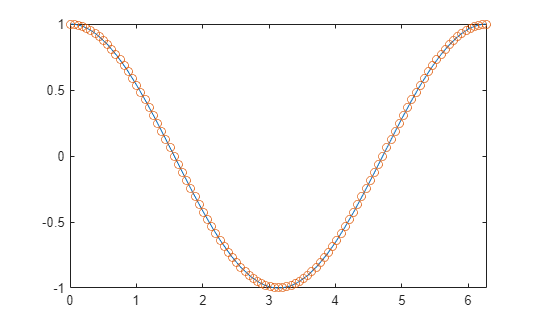


T= t(2)-t(1);
dfdt=gradient(f_t,T);

fplot(dfdt_c,[0,2*pi])
hold on
plot (t,dfdt,"o")
hold off

## Reconstruction

p=polyfit(t,f_t,4);
f_t_reconstructed= polyval(p,t_recon);
t_recon = t

t_recon =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


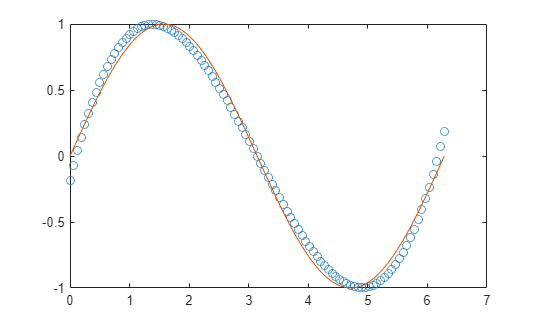


plot(t_recon,f_t_reconstructed,"o")
hold on
plot(t,f_t)